syms qi ra tha thw r cw cm thwp thmp thm s

thwp=(1/cw)*(qi+(1/ra)*(tha-thw)-(1/r)*(thw-thm))

$$thwp = \frac{\mathrm{qi}+\frac{\mathrm{thm}-\mathrm{thw}}{r}+\frac{\mathrm{tha}-\mathrm{thw}}{\mathrm{ra}}}{\mathrm{cw}}$$

thmp=(1/cm)*((1/r)*(thw-thm))

$$thmp = -\frac{\mathrm{thm}-\mathrm{thw}}{\mathrm{cm}\,r}$$

xe=[thw,thm]

$$xe = \left(\begin{array}{cc} \mathrm{thw} & \mathrm{thm} \end{array}\right)$$

y=thm

$$y = \mathrm{thm}$$

A=jacobian([thwp,thmp],xe)

$$A = \left(\begin{array}{cc} -\frac{\frac{1}{r}+\frac{1}{\mathrm{ra}}}{\mathrm{cw}} & \frac{1}{\mathrm{cw}\,r}\\ \frac{1}{\mathrm{cm}\,r} & -\frac{1}{\mathrm{cm}\,r} \end{array}\right)$$

B=jacobian([thwp,thmp],qi)

$$B = \left(\begin{array}{c} \frac{1}{\mathrm{cw}}\\ 0 \end{array}\right)$$

C=jacobian(y,xe)

$$C = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$

D=jacobian(y,qi)

$$D = 0$$

%%%%% P.op
tha=20+273;

Fs=C*(inv(s*eye(2)-A))*B+D

$$Fs = \frac{\mathrm{ra}}{\mathrm{cm}\,r\,s+\mathrm{cm}\,\mathrm{ra}\,s+\mathrm{cw}\,\mathrm{ra}\,s+\mathrm{cm}\,\mathrm{cw}\,r\,\mathrm{ra}\,s^{2}+1}$$

simplify(Fs)

$$ans = \frac{\mathrm{ra}}{\mathrm{cm}\,r\,s+\mathrm{cm}\,\mathrm{ra}\,s+\mathrm{cw}\,\mathrm{ra}\,s+\mathrm{cm}\,\mathrm{cw}\,r\,\mathrm{ra}\,s^{2}+1}$$


ra=10;
r=30;
cw=0.5;
cm=0.01;

A=double(eval(A))

A =    -0.2667    0.0667
    3.3333   -3.3333


B=double(eval(B))

B =      2
     0


C=double(eval(C))

C =      0     1


D=double(eval(D))

D = 0


[num,den]=ss2tf(A,B,C,D)

num =          0         0    6.6667


den =     1.0000    3.6000    0.6667


ft=tf(num,den)

ft =
 
         6.667
  --------------------
  s^2 + 3.6 s + 0.6667
 
Continuous-time transfer function.



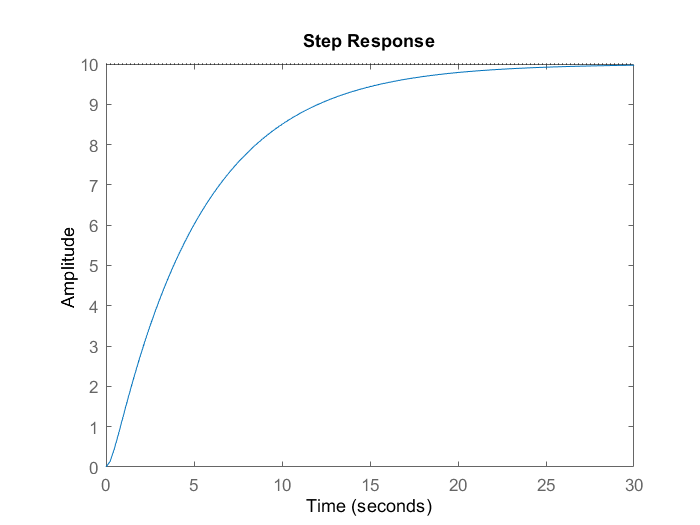

step(ft)

ts=35

ts = 35

zeta=0.2

zeta = 0.2000

wn=4/(ts*zeta)

wn = 0.5714

polos=roots([1 2*zeta*wn wn^2])

polos =   -0.1143 + 0.5599i
  -0.1143 - 0.5599i


K=acker(A,B,polos)

K =    -1.6857    1.6347


%PARA ESS=0 RAMPA
polosEss=conv(polos,[1 5*wn*zeta])

polosEss =   -0.1143 + 0.5599i  -0.1796 - 0.2400i  -0.0653 - 0.3199i


polosEss=conv(polosEss,[1 5*wn*zeta])

polosEss =   -0.1143 + 0.5599i  -0.2449 + 0.0800i  -0.1679 - 0.4570i  -0.0373 - 0.1828i


Aempaq=[A(1,1),A(1,2),0,0;A(2,1),A(2,2),0,0;0,0,0,1;-C(1,1),-C(1,2),0,0]

Aempaq =    -0.2667    0.0667         0         0
    3.3333   -3.3333         0         0
         0         0         0    1.0000
         0   -1.0000         0         0


Bempaq=[B(1,1);B(2,1);0;0]

Bempaq =      2
     0
     0
     0


K1=acker(Aempaq,Bempaq,polosEss)

K1 =    -1.5178    1.4761   -0.0012   -0.0139


## Tm=3s

tm=3

tm = 3

polosEssT=conv(polosEss,[1 5*wn*zeta])

polosEssT =   -0.1143 + 0.5599i  -0.3102 + 0.3999i  -0.3079 - 0.4113i  -0.1333 - 0.4440i  -0.0213 - 0.1045i


polosEssT=conv(polosEssT,[1 5*wn*zeta])

polosEssT =   -0.1143 + 0.5599i  -0.3755 + 0.7199i  -0.4851 - 0.1828i  -0.3092 - 0.6790i  -0.0975 - 0.3582i  -0.0122 - 0.0597i


ftdelay=tf([1],[(tm^2)/2 tm 1])

ftdelay =
 
          1
  -----------------
  4.5 s^2 + 3 s + 1
 
Continuous-time transfer function.



ft2=ft*ftdelay

ft2 =
 
                      6.667
  ----------------------------------------------
  4.5 s^4 + 19.2 s^3 + 14.8 s^2 + 5.6 s + 0.6667
 
Continuous-time transfer function.



[A1,B1,C1,D1]=tf2ss(6.667,[4.5,19.2,14.8,5.6,0.6667])

A1 =    -4.2667   -3.2889   -1.2444   -0.1482
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B1 =      1
     0
     0
     0


C1 =          0         0         0    1.4816


D1 = 0

Aempaq1=[A1(1,1),A1(1,2),A1(1,3),A1(1,4),0,0;A1(2,1),A1(2,2),A1(2,3),A1(2,4),0,0;A1(3,1),A1(3,2),A1(3,3),A1(3,4),0,0;A1(4,1),A1(4,2),A1(4,3),A1(4,4),0,0;0,0,0,0,0,1;-C1(1,1),-C1(1,2),-C1(1,3),-C1(1,4),0,0]

Aempaq1 =    -4.2667   -3.2889   -1.2444   -0.1482         0         0
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0         0         0    1.0000
         0         0         0   -1.4816         0         0


Bempaq1=[B1(1,1);B1(2,1);B1(3,1);B1(4,1);0;0]

Bempaq1 =      1
     0
     0
     0
     0
     0


KDelay=acker(Aempaq1,Bempaq1,polosEssT)

KDelay =    -2.8729   -1.8359   -0.4572    0.1506    0.0004   -0.0452


%%Observador
tsa=ts/10;
wna=4/(tsa*zeta)

wna = 5.7143

obs=[C;C*A]

obs =          0    1.0000
    3.3333   -3.3333


det(obs)

ans = -3.3333

pdo=conv([1 2*tsa*zeta wna^2],[1 10*wna*zeta])

pdo =     1.0000   12.8286   48.6531  373.1778


phia= A^3+pdo(2)*A^2+pdo(3)*A+pdo(4)*eye(2)

phia =   363.0885    0.9842
   49.2118  317.8137


L=phia*(inv(obs))*[1;0]

L =   364.0728
  367.0255
